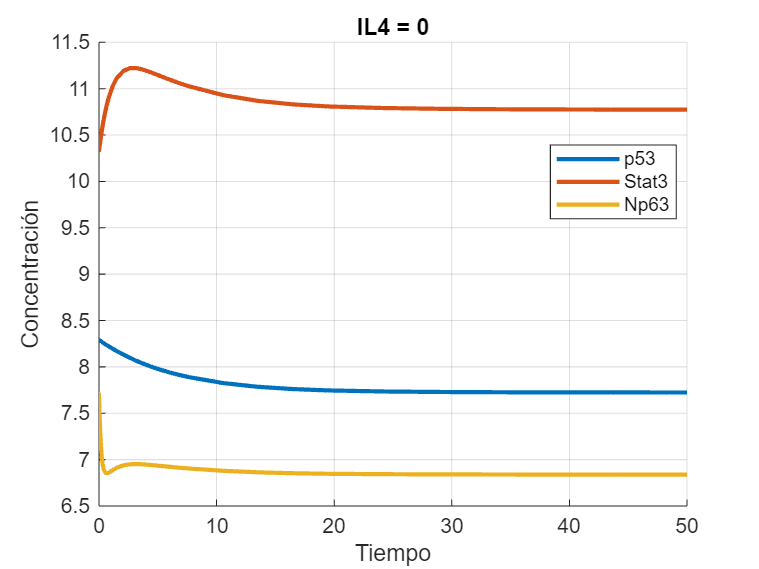

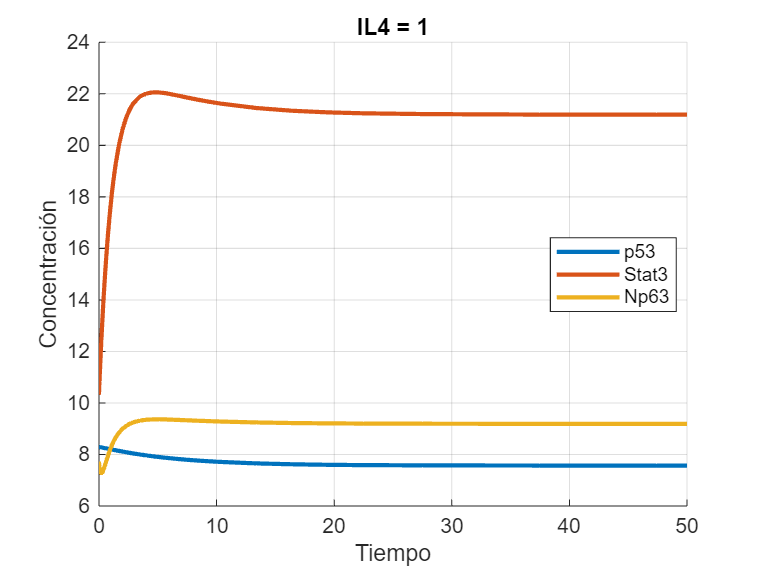

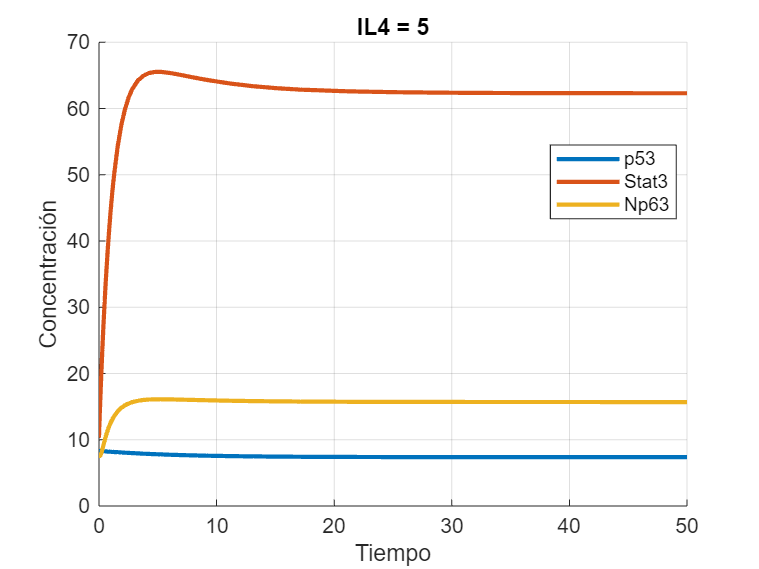

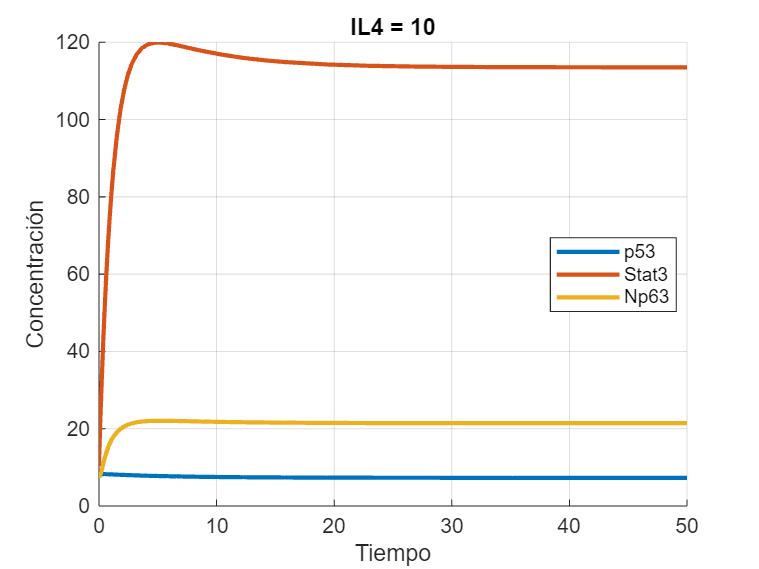

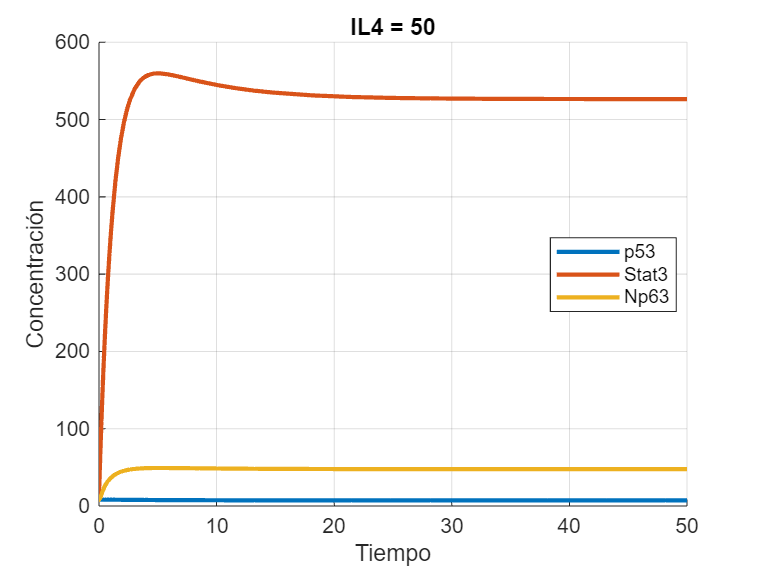

% Preparación del entorno
clear;
clc;
close all;

% Definición simbólica del sistema
syms p53 Stat3 Np63 IL4

% Parámetros fijos
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
Pstat3 = 0.9819;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53)*(1+IL4) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

vars = [p53, Stat3, Np63];

IL4_vals = [0, 1, 5, 10, 50];
tspan = [0 50];           % Tiempo de simulación
x0_experimental = [8.293; 10.32066667; 7.721333333];      % Condición inicial
x0_prueba = [7.2; 500; 50]; 

x0 = x0_experimental;

soluciones = cell(length(IL4_vals), 1);

for i = 1:length(IL4_vals)
    IL4 = IL4_vals(i);
    ode_func = @(t,x) sistema_dinamico(t, x, IL4);
    [T, X] = ode15s(ode_func, tspan, x0);
    soluciones{i} = struct('T', T, 'X', X);
end

varNames = {'p53', 'Stat3', 'Np63'};
colores = lines(3);  % colores diferentes para cada variable

for i = 1:length(IL4_vals)
    T = soluciones{i}.T;
    X = soluciones{i}.X;

    figure;
    hold on;
    for v = 1:3
        plot(T, X(:,v), 'LineWidth', 2, 'Color', colores(v,:));
    end
    xlabel('Tiempo');
    ylabel('Concentración');
    title(['IL4 = ', num2str(IL4_vals(i))]);
    legend(varNames, 'Location', 'best');
    grid on;
end

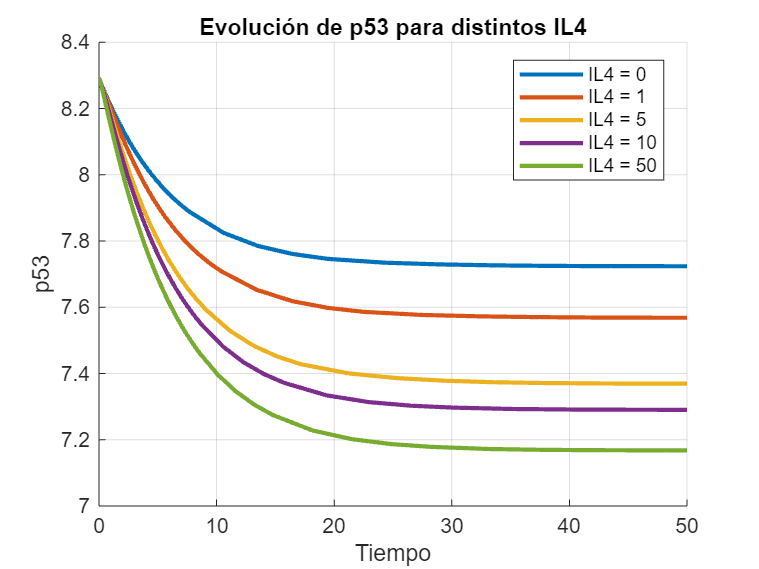

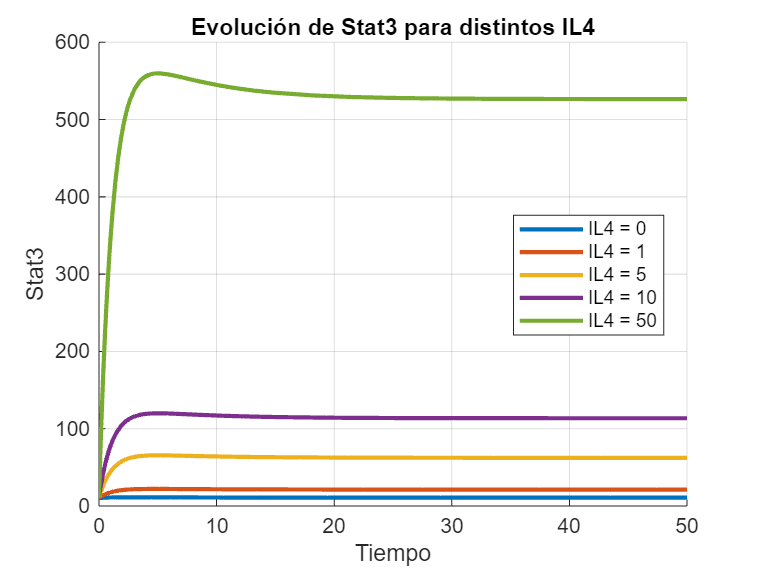

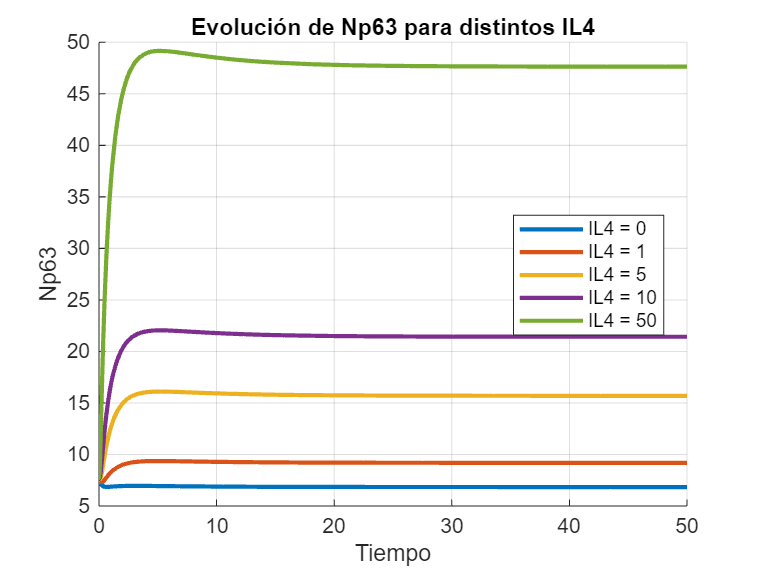


for v = 1:3
    figure; hold on;  % Crear una figura nueva por variable
    for i = 1:length(IL4_vals)
        T = soluciones{i}.T;
        X = soluciones{i}.X;
        plot(T, X(:,v), 'LineWidth', 2, ...
             'DisplayName', ['IL4 = ' num2str(IL4_vals(i))]);
    end
    xlabel('Tiempo'); ylabel(varNames{v});
    title(['Evolución de ' varNames{v} ' para distintos IL4']);
    legend('Location', 'best');
    grid on;
end



function dxdt = sistema_dinamico(t, x, IL4)
    % Desempaquetar variables
    p53 = x(1);
    Stat3 = x(2);
    Np63 = x(3);

    % Parámetros
    Pp53 = 1.1380;
    N = 0.6184;
    k = 1.8558;
    B = 1.6019;
    ANp63p53 = 1.3864;
    C1 = 0.8905;
    dNp63p53 = 1.0944;
    Dp53 = 0.1597;
    Pstat3 = 0.9819;
    ANp63s = 0.0053;
    Ap53s = 1.1090;
    Dstat3 = 0.8895;
    PNp63 = 5.7201;
    Astat3Np = 0.9350;
    C2 = 1.2659;
    dp53NP = 0.0000;
    C3 = 2.8150;
    dNp63Np63 = 0.2113;
    DNp63 = 3.3663;

    % Ecuaciones del sistema (derivadas)
    dxdt = zeros(3,1);
    dxdt(1) = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * ...
              C1/(1 + dNp63p53*Np63) - Dp53*p53;

    dxdt(2) = (Pstat3 + ANp63s*Np63 + Ap53s*p53)*(1+IL4) - Dstat3*Stat3;

    dxdt(3) = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * ...
              C3/(1 + dNp63Np63*Np63) - DNp63*Np63;
end